# Miami AI demo

## Data Prep

% Define the time range
startTime = datetime('now'); % Current time
endTime = startTime + days(3); % 3 days later
timeVector = startTime:hours(3):endTime; % Sampling every 3 hours

% Generate random temperature data (for example purposes)
temperatureData = randi([15, 30], length(timeVector), 1); % Random temperatures between 15 and 30 degrees

% Create the table
temperatureForecast = table(timeVector', temperatureData, ...
    'VariableNames', {'Time', 'Temperature'});

% Display the table
temperatureForecast

temperatureForecast = 25×2 table
            Time            Temperature
    ____________________    ___________

    04-Mar-2025 10:41:34        28     
    04-Mar-2025 13:41:34        29     
    04-Mar-2025 16:41:34        17     
    04-Mar-2025 19:41:34        29     
    04-Mar-2025 22:41:34        25     
    05-Mar-2025 01:41:34        16     
    05-Mar-2025 04:41:34        19     
    05-Mar-2025 07:41:34        23     
    05-Mar-2025 10:41:34        30     
    05-Mar-2025 13:41:34        30     
    05-Mar-2025 16:41:34        17     
    05-Mar-2025 19:41:34        30     
    05-Mar-2025 22:41:34        30     
    06-Mar-2025 01:41:34        22     
    06-Mar-2025 04:41:34        27     
    06-Mar-2025 07:41:34        17     


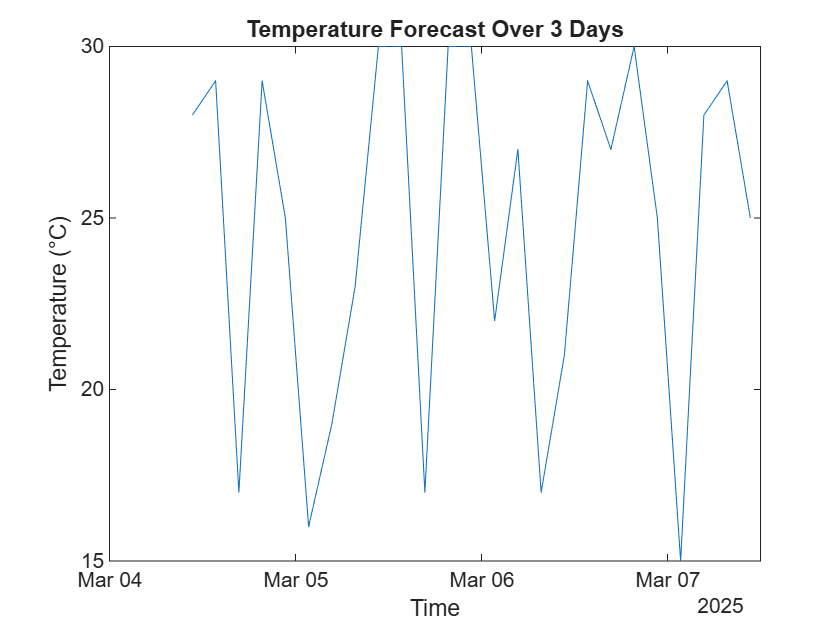

plot(temperatureForecast.Time,temperatureForecast.Temperature)
% Add labels and title to the plot
xlabel('Time');
ylabel('Temperature (°C)');
title('Temperature Forecast Over 3 Days');

## Live task

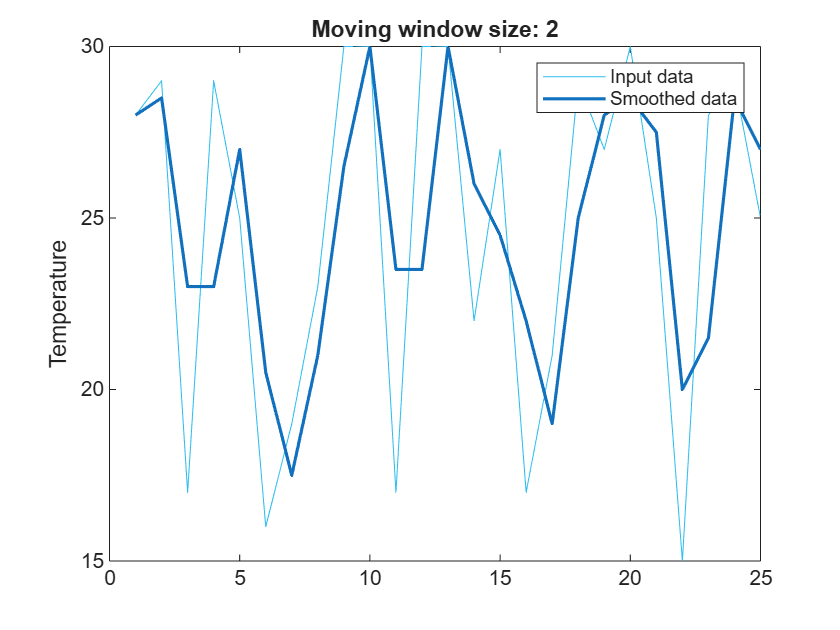

% Smooth input data
[newTable,winSize] = smoothdata(temperatureForecast, ...
    "movmean",SmoothingFactor=0.25,DataVariables="Temperature");

% Display results
figure
plot(temperatureForecast.Temperature,SeriesIndex=6,DisplayName="Input data")
hold on
plot(newTable.Temperature,SeriesIndex=1,LineWidth=1.5, ...
    DisplayName="Smoothed data")
hold off
title("Moving window size: " + string(winSize));
legend
ylabel("Temperature")

clear winSize
